# **Laboratorio 5**

# **Cinemática Inversa Robot Phantom**

**Nikolai Alexander Cáceres Penagos – Andrés Felipe Forero Salas - IvanMauricio Hernández Triana**

El modelo cinemático inverso se fundamenta en el método geométrico. Partiendo de una posición del marcador expresada como.


$$d_m^B =\left\lbrack \begin{array}{c}
x_m \\
y_m \\
z_m 
\end{array}\right\rbrack$$


Y una orientación perpendicular al tablero ubicado en el suelo. Para el desarrollo del modelo, se parte del diagrama simplificado del Manipulador Phantom X desde la vista superior.

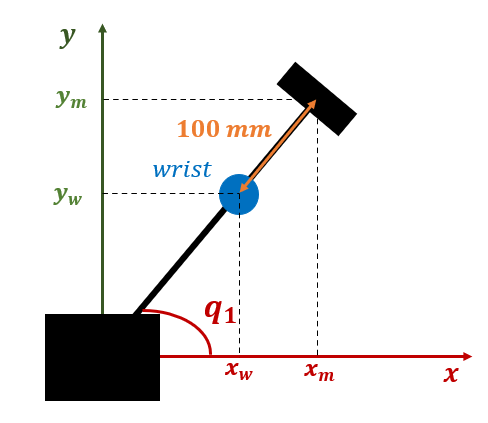

De esta forma, el ángulo de rotación de la articulación 1 será facilmente encontrado con la posición en el plano XY del marcador.


$$q_1 =\tan^{-1} \;\left(\frac{y_m }{x_m }\right)$$


Adicionalmente, será importante conocer la posición en dicho plano de la muñeca del manipulador.


$$d_w^B =\left\lbrack \begin{array}{c}
x_w \\
y_w \\
z_m 
\end{array}\right\rbrack =d_m^B -100\;\left\lbrack \begin{array}{c}
\cos \;\left(q_1 \right)\\
\sin \;\left(q_1 \right)\\
0
\end{array}\right\rbrack \;\mathrm{mm}$$


Para encontrar el valor de las cuatro posiciones angulares restantes, se emplea una vista perpendicular a este ángulo $q_1$, para observar distancias de interes en magnitud verdadera.

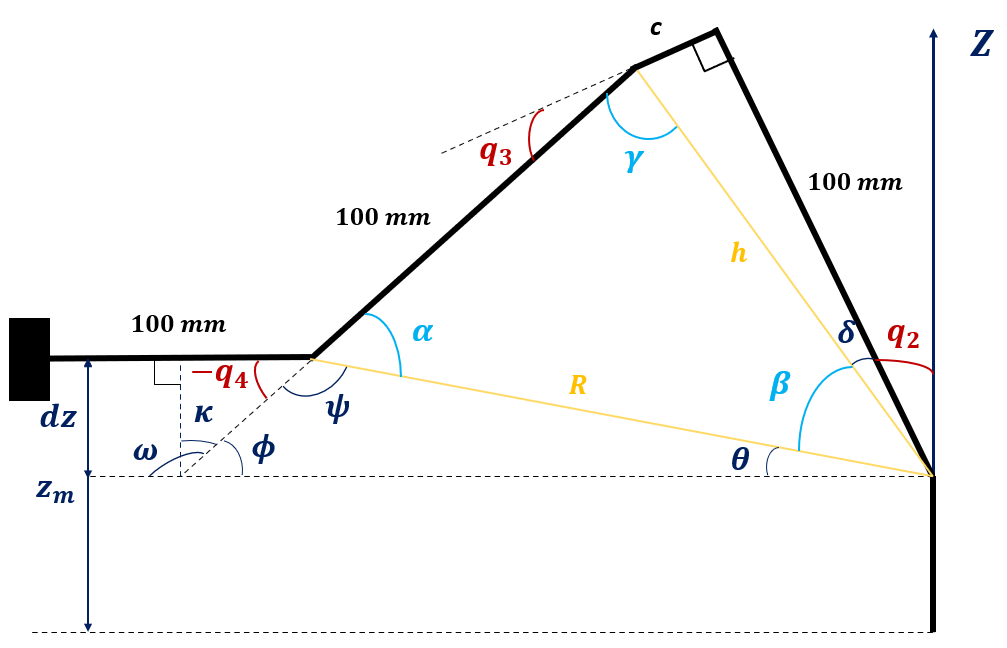

Del manipulador físico se encuentra la distancia ***h*** reportada como.


$$h=106\ldotp 5\;\mathrm{mm}$$


Con este parámetro y la medida del eslabón del robot encontramos el cateto ***c ***y el ángulo $\delta \;$.


$$c\;=\sqrt{h^2 -{100}^2 }=36\ldotp 6367\;\mathrm{mm}$$



$$\delta =\tan^{-1} \;\left(\frac{c}{100}\right)=20\ldotp 1212\degree$$


Para continuar con la solución del modelo, se encuentra la longitud del parámetro *R,  *para lo cual se debe encontrar la distancia *dz.*


$$\mathrm{dz}=z_m -94\ldotp 4\;\mathrm{mm}$$



$$R=\sqrt{x_w^2 +y_w^2 +{\mathrm{dz}}^2 }$$


Conocida esta dimensión, podemos hallar los ángulos internos del triángulo, a través del teorema del coseno.


$$\alpha =\cos^{-1} \left(\frac{{100}^2 +r^2 -h^2 }{2\cdot 100\cdot r}\right)$$



$$\beta \;=\cos^{-1} \left(\frac{h^2 +r^2 -{100}^2 }{2\cdot r\cdot h}\right)$$



$$\gamma \;=\cos^{-1} \left(\frac{h^2 +{100}^2 -r^2 }{2\cdot 100\cdot h}\right)$$


Con estos ángulos conocidos, se utilizan relaciones geométricas que nos permitan encontrar el valor de los demás ángulos de la figura para de esta forma finalmente encontrar las posiciones angulares de las articulaciones del robot.


$$\theta =\sin^{-1} \left(\frac{\mathrm{dz}}{R}\right)$$



$$\psi =180\degree -\alpha$$



$$\phi =180\degree -\psi -\theta$$



$$\omega =180\degree -\phi$$



$$\kappa =\omega -90\degree$$


Con lo que las posiciones angulares de las articulaciones del manipulador se encuentran determinadas por las ecuaciones.


$$q_2 =90\degree -\theta -\beta -\delta \;$$



$$q_3 =90\degree -\gamma +\delta \;$$



$$q_4 =\kappa -90\degree$$


function [q1,q2,q3,q4]=phinv(x,y,z)
    %Triangulo constante
    h=106.5;%distancia diagonal entre q2 y q3
    c=sqrt(h^2-100^2); %cateto de la diagonal
    delta = atan2(c,100);

    q1=atan2(y,x);

    dmar0 = [x y z 1]'; %Posición del marcador
    d3 = 100*[cos(q1) sin(q1) 0 1/100]'; %Posición de la muñeca desde el marcador
    dw0 = dmar0-d3; %Posición de la muñeca desde la base

    %Altura relativa de la muñeca
    dz = dw0(3)-94;

    %Distancia de la muñeca al eje de la articulación2
    r2 = (dw0(1))^2+(dw0(2))^2+(dz)^2;
    r = sqrt(r2);

    %Teorema del coseno
    alpha = acos((100^2+r2-h^2)/(2*r*100));
    beta = acos((r2+h^2-100^2)/(2*r*h));
    gamma = acos((h^2+100^2-r2)/(2*h*100));

    %Ángulos auxiliares
    theta = atan2(dz,sqrt((dw0(1))^2+(dw0(2))^2));
    psi = pi-alpha;
    phi = pi-psi-theta;
    omega = pi-phi;
    kappa = omega-pi/2;

    %Posiciones angulares del manipulador
    q2= pi/2-theta-beta-delta;
    q3= pi-gamma-(pi/2-delta);
    q4 = -(pi/2-kappa);
end